I = imread("rice.png")

I = 256×256 uint8 matrix
   122    92    95    99   102   107    89    90    95   110    91    96    81    87    93    94   106    89   126   104   122   188   192   192   184   172   182   179   178   127   105   110   100   105   119    91   114    99   105   100    94   109    96   102    97    90    92   101   109    92
    99    99   102    82   100    89    91    87    86    94    87    98    92   111    97    93    99    90   102   100   158   185   181   185   179   176   181   181   156   104   107   102   102   103   110    95   104    93   101    95    94   102   100    92    90    88    94   112    95    95
    97   107   103    86    98    92    93    96    96    93   100   121    96   103    89    96   106    94   101   116   181   177   175   175   176   176   178   175   105   104    98   100    91   106   107    98   104    96   103    86   100    97    93   112    97    86    94    96    86   108
   102   100    99    87    97    89   110    95    93    83    89   103


%finds comatrix with given displacement vectors
C_D12 = graycomatrix(I, 'Offset', [1 2])

C_D12 =            0           0           0           0           0           0           0           0
           0        7764        1053         171         127           0           0           0
           0        1206        9251        2266         488         196           1           0
           0         189        2303       19130        1150        1839         241           0
           0         164         480        1129        2189         767         146           0
           0           0         289        1809         815        6014         919           0
           0           0           0         310         136         899        1329           0
           0           0           0           0           0           0           0           0


C_D22 = graycomatrix(I, 'Offset', [2 2])

C_D22 =            0           0           0           0           0           0           0           0
           0        7470        1072         215         155           0           0           0
           0        1399        8633        2445         624         290           2           0
           0         228        2640       18238        1138        2214         377           0
           0         226         589        1131        2000         743         167           0
           0           0         393        2209         829        5479         936           0
           0           0           0         454         148         928        1144           0
           0           0           0           0           0           0           0           0


C_D23 = graycomatrix(I, 'Offset', [2 3])

C_D23 =            0           0           0           0           0           0           0           0
           0        7284        1033         279         285           0           0           0
           0        1382        8427        2301         736         497           2           0
           0         280        2511       17341        1145        2843         609           0
           0         349         717        1134        1721         704         198           0
           0           0         585        2898         798        4611         924           0
           0           0           4         671         179         937         877           0
           0           0           0           0           0           0           0           0


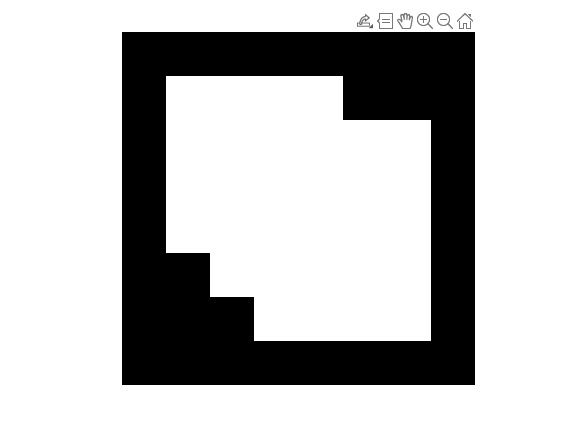


imshow(C_D12)

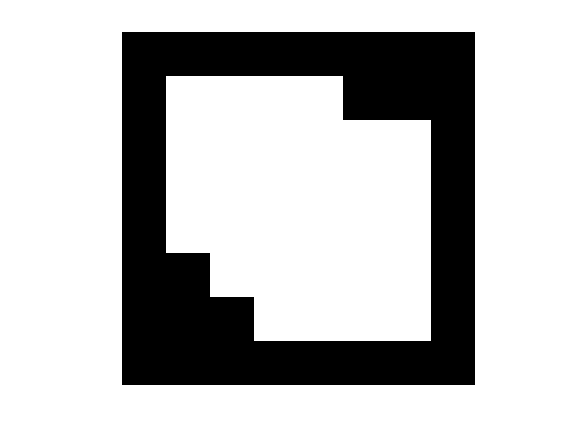

imshow(C_D22)

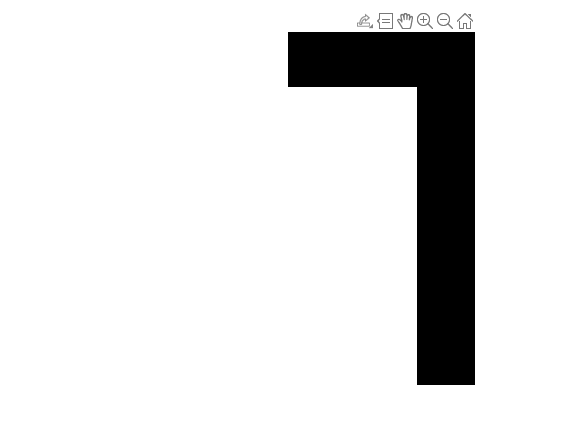

imshow(C_D23)


N_D12 = (C_D12)/sum(C_D12, 'all')

N_D12 =          0         0         0         0         0         0         0         0
         0    0.1199    0.0163    0.0026    0.0020         0         0         0
         0    0.0186    0.1428    0.0350    0.0075    0.0030    0.0000         0
         0    0.0029    0.0356    0.2954    0.0178    0.0284    0.0037         0
         0    0.0025    0.0074    0.0174    0.0338    0.0118    0.0023         0
         0         0    0.0045    0.0279    0.0126    0.0929    0.0142         0
         0         0         0    0.0048    0.0021    0.0139    0.0205         0
         0         0         0         0         0         0         0         0


N_D22 = (C_D22/sum(C_D22, 'all'))

N_D22 =          0         0         0         0         0         0         0         0
         0    0.1158    0.0166    0.0033    0.0024         0         0         0
         0    0.0217    0.1338    0.0379    0.0097    0.0045    0.0000         0
         0    0.0035    0.0409    0.2827    0.0176    0.0343    0.0058         0
         0    0.0035    0.0091    0.0175    0.0310    0.0115    0.0026         0
         0         0    0.0061    0.0342    0.0128    0.0849    0.0145         0
         0         0         0    0.0070    0.0023    0.0144    0.0177         0
         0         0         0         0         0         0         0         0


N_D23 = (C_D23/sum(C_D23, 'all'))

N_D23 =          0         0         0         0         0         0         0         0
         0    0.1133    0.0161    0.0043    0.0044         0         0         0
         0    0.0215    0.1311    0.0358    0.0115    0.0077    0.0000         0
         0    0.0044    0.0391    0.2698    0.0178    0.0442    0.0095         0
         0    0.0054    0.0112    0.0176    0.0268    0.0110    0.0031         0
         0         0    0.0091    0.0451    0.0124    0.0718    0.0144         0
         0         0    0.0001    0.0104    0.0028    0.0146    0.0136         0
         0         0         0         0         0         0         0         0


graycoprops(C_D12)

ans = struct with fields:
       Contrast: 0.7025
    Correlation: 0.8075
         Energy: 0.1384
    Homogeneity: 0.8340


graycoprops(C_D22)

ans = struct with fields:
       Contrast: 0.8668
    Correlation: 0.7622
         Energy: 0.1276
    Homogeneity: 0.8091


graycoprops(C_D23)

ans = struct with fields:
       Contrast: 1.1274
    Correlation: 0.6907
         Energy: 0.1185
    Homogeneity: 0.7805



E_12 = findEntropy(N_D12)

E_12 = 2.5032

E_22 = findEntropy(N_D22)

E_22 = 2.5846

E_32 = findEntropy(N_D23)

E_32 = 2.6617